read_file = fopen('chr1_shapes_orchid.txt','rt');
write_file = fopen('chr1_shape_matrices_orchid.txt', 'wt');
thisline = fgetl(read_file);
thisline = fgetl(read_file);
C = strsplit(thisline,"\t");
n1 = C(1,1);
n1 = str2double(n1{1});
orchid = C(1,3);
orchid = str2double(orchid{1});

matrx = [orchid];
n = [n1];

for k=1:21
    thisline = fgetl(read_file);
    C = strsplit(thisline,"\t");
    n1 = C(1,1);
    n1 = str2double(n1{1});

    orchid = C(1,3);
    orchid = str2double(orchid{1});
    
    matrx = [matrx; orchid];
    n = [n; n1];
end

matrx

matrx =     0.4758
   -0.0963
    0.0968
   -0.0367
    0.0374
    0.5261
    0.5727
   -0.0428
    0.3656
    0.4249


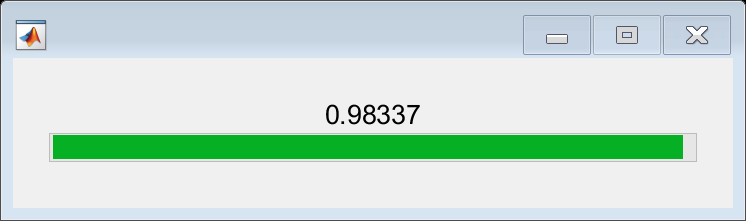


loading = waitbar(0,'Please wait...');
for i=1:398000
    r = i/398000;
    progress = round(r,5);
    waitbar(progress,loading,string(progress));
    
    matrx_row = matrx(:)';
    n_current = n(1, 1);
    
    fprintf(write_file,'%12d\t %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f %12f\n',n_current, matrx_row);
    
    thisline = fgetl(read_file);
    if ~ischar(thisline); break; end  %end of file
    
    n(1, :) = [];
    matrx(1, :) = [];
    
    C = strsplit(thisline,"\t");
    n1 = C(1,1);
    n1 = str2double(n1{1});

    orchid = C(1,3);
    orchid = str2double(orchid{1});
    
    matrx = [matrx; orchid];
    n = [n; n1];
end


fclose(read_file);
fclose(write_file);
